# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240211'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'solitary multi-flavor foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {'14662'}; % in order of serial number list
bname_ephys = {'14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,2,0,0; 2,1,0,0; 1,2,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662 



trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\20240211_111914_merged.rec" -outputdirectory Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\Processed -interp 0
Using the following workspace file:  "20240211_111914_merged.trodesconf"
Exporting data...
0.9705%1.941%2.911%A gap of 233 packets occured in the file. Last timestamp:  7784835 (Clock is:  "00:04:19" )
3.881%4.852%5.822%A gap of 2 packets occured in the file. Last timestamp:  14189997 (Clock is:  "00:07:52" )
6.792%A gap of 255 packets occured in the file. Last timestamp:  15340769 (Clock is:  "00:08:31" )
7.763%8.733%A gap of 2 packets occured in the file. Last timestamp:  18959997 (Clock is:  "00:10:31" )
9.703%10.67%11.64%12.61%A gap of 49 packets occure

chanmap_file = struct with fields:
       name: '20240211_111914_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\Processed\20240211_111914_merged.kilosort'
       date: '14-Feb-2024 18:31:15'
      bytes: 2529
      isdir: 0
    datenum: 7.3930e+05


chanmap_file = struct with fields:
       name: '20240211_111914_merged.channelmap_probe2.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\Processed\20240211_111914_merged.kilosort'
       date: '14-Feb-2024 18:31:15'
      bytes: 3369
      isdir: 0
    datenum: 7.3930e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\Processed\20240211_111914_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  13s. Loading raw data and applying filters... 
Time 297s. Finished preprocessing 1414 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1402

0.19 sec, 1 batches, 3215 spikes 
18.19 sec, 101 batches, 375941 spikes 
36.52 sec, 201 batches, 752535 spikes 
56.24 sec, 301 batches, 1093931 spikes 
77.40 sec, 401 batches, 1405397 spikes 
99.90 sec, 501 batches, 1721688 spikes 
123.68 sec, 601 batches, 2080526 spikes 
148.88 sec, 701 batches, 2402070 spikes 
175.53 sec, 801 batches, 2704520 spikes 
203.65 sec, 901 batches, 3030961 spikes 
233.02 sec, 1001 batches, 3351206 spikes 
264.01 sec, 1101 batches, 3661868 spikes 
296.28 sec, 1201 batches, 3983754 spikes 
329.97 sec, 1301 batches, 4335912 spikes 
365.18 sec, 1401 batches, 4658086 spikes 
369.86 sec, 1414 batches, 4698684 spikes 


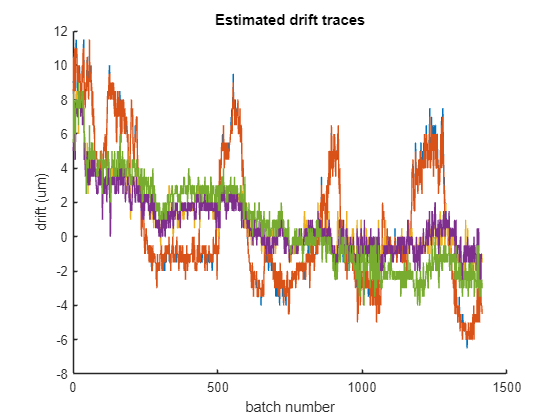

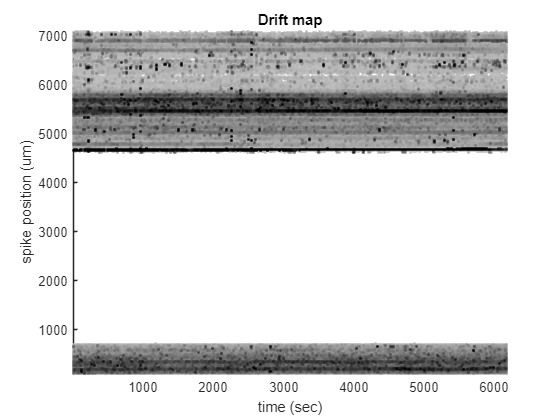

time 933.17, Shifted up/down 1414 batches. 
0.35 sec, 1 batches, 7465 spikes 
33.44 sec, 101 batches, 861419 spikes 
66.64 sec, 201 batches, 1813836 spikes 
99.87 sec, 301 batches, 2787861 spikes 
132.94 sec, 401 batches, 3764908 spikes 
165.99 sec, 501 batches, 4745980 spikes 
199.43 sec, 601 batches, 5732512 spikes 
232.50 sec, 701 batches, 6732506 spikes 
265.66 sec, 801 batches, 7731591 spikes 
299.40 sec, 901 batches, 8731591 spikes 
332.49 sec, 1001 batches, 9725966 spikes 
365.71 sec, 1101 batches, 10715135 spikes 
399.74 sec, 1201 batches, 11708152 spikes 
432.90 sec, 1301 batches, 12707936 spikes 
467.10 sec, 1401 batches, 13694279 spikes 
471.44 sec, 1414 batches, 13821492 spikes 
time 0.00, GROUP 1/352, units 0 
time 3.14, GROUP 6/352, units 7 
time 5.43, GROUP 11/352, units 12 
time 7.21, GROUP 16/352, units 17 
time 7.46, GROUP 21/352, units 18 
time 7.46, GROUP 26/352, units 18 
time 7.46, GROUP 31/352, units 18 
time 7.46, GROUP 36/352, units 18 
time 7.46, GROUP 41/352,

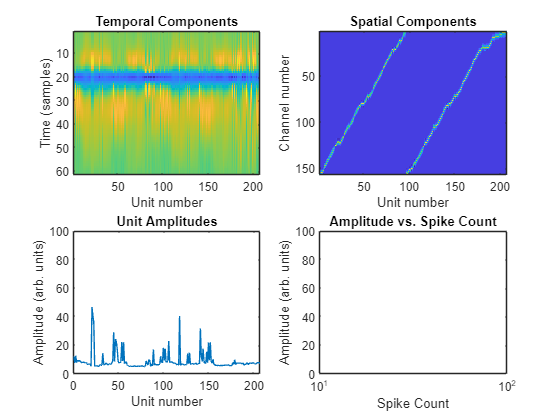

time 0.00, GROUP 1/352, units 0 
time 0.02, GROUP 6/352, units 0 
time 0.03, GROUP 11/352, units 0 
time 0.05, GROUP 16/352, units 0 
time 0.06, GROUP 21/352, units 0 
time 0.07, GROUP 26/352, units 0 
time 0.09, GROUP 31/352, units 0 
time 0.10, GROUP 36/352, units 0 
time 0.11, GROUP 41/352, units 0 
time 0.12, GROUP 46/352, units 0 
time 0.13, GROUP 51/352, units 0 
time 0.13, GROUP 56/352, units 0 
time 0.14, GROUP 61/352, units 0 
time 0.15, GROUP 66/352, units 0 
time 0.15, GROUP 71/352, units 0 
time 0.16, GROUP 76/352, units 0 
time 0.16, GROUP 81/352, units 0 
time 0.17, GROUP 86/352, units 0 
time 0.17, GROUP 91/352, units 0 
time 0.18, GROUP 96/352, units 0 
time 0.19, GROUP 101/352, units 0 
time 0.19, GROUP 106/352, units 0 
time 0.20, GROUP 111/352, units 0 
time 2.17, GROUP 116/352, units 6 
time 4.80, GROUP 121/352, units 11 
time 9.76, GROUP 126/352, units 20 
time 15.72, GROUP 131/352, units 25 
time 21.11, GROUP 136/352, units 32 
time 29.78, GROUP 141/352, units 39 

ans = 14

initialized spike counts
merged 14 into 16 
merged 96 into 94 
merged 69 into 73 


ans = 11

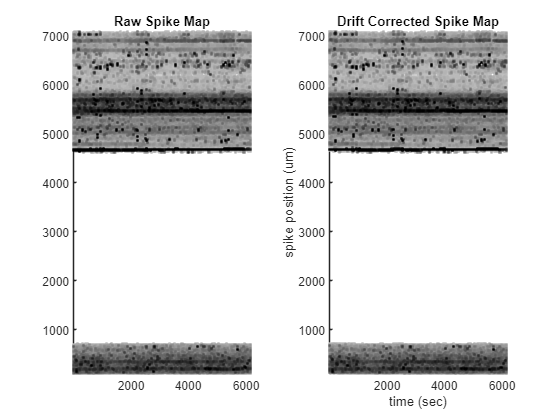

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [157×1 double]
                 yc: [157×1 double]
            xcoords: [157×1 double]
            ycoords: [157×1 double]
               Wrot: [157×157 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×157 gpuArray]
               dist: [10×1408 single]
              iorig: [1414×1 double]
             dshift: [1414×5 double]
                st0: [4698684×6 double]
                  F: [1402×20×1414 double]
                 F0: [1402×20 gpuArray]
                F0m: [1402×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×1408 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0

Looking for data inside Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211\ephys\20240211_111914.rec\14662\Processed\20240211_111914_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  15s. Loading raw data and applying filters... 
Time 412s. Finished preprocessing 1414 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

   906

0.23 sec, 1 batches, 4283 spikes 
25.44 sec, 101 batches, 539900 spikes 
51.49 sec, 201 batches, 1074127 spikes 
79.52 sec, 301 batches, 1586514 spikes 
109.63 sec, 401 batches, 2028273 spikes 
141.84 sec, 501 batches, 2450309 spikes 
175.95 sec, 601 batches, 2970946 spikes 
212.21 sec, 701 batches, 3436306 spikes 
250.47 sec, 801 batches, 3871817 spikes 
290.70 sec, 901 batches, 4336554 spikes 
332.90 sec, 1001 batches, 4801731 spikes 
377.16 sec, 1101 batches, 5248640 spikes 
424.60 sec, 1201 batches, 5712007 spikes 
475.91 sec, 1301 batches, 6240535 spikes 
531.23 sec, 1401 batches, 6692569 spikes 
538.78 sec, 1414 batches, 6751551 spikes 


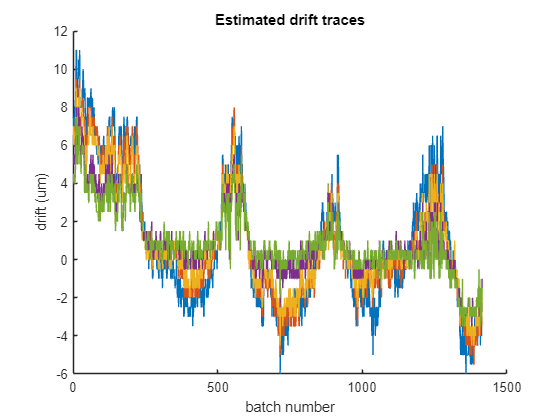

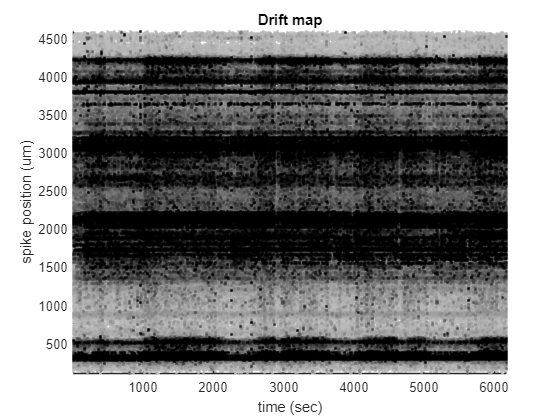

time 1391.92, Shifted up/down 1414 batches. 
0.57 sec, 1 batches, 8547 spikes 
53.69 sec, 101 batches, 951451 spikes 
107.00 sec, 201 batches, 1918617 spikes 
159.99 sec, 301 batches, 2901714 spikes 
213.12 sec, 401 batches, 3899143 spikes 
266.30 sec, 501 batches, 4897071 spikes 
320.08 sec, 601 batches, 5866124 spikes 
373.29 sec, 701 batches, 6863414 spikes 
426.62 sec, 801 batches, 7857721 spikes 
480.53 sec, 901 batches, 8857486 spikes 
533.77 sec, 1001 batches, 9856156 spikes 
587.08 sec, 1101 batches, 10854334 spikes 
641.17 sec, 1201 batches, 11854205 spikes 
694.48 sec, 1301 batches, 12854054 spikes 
748.79 sec, 1401 batches, 13828739 spikes 
755.73 sec, 1414 batches, 13958543 spikes 
time 0.00, GROUP 1/228, units 0 
time 1.45, GROUP 6/228, units 7 
time 5.12, GROUP 11/228, units 19 
time 6.72, GROUP 16/228, units 25 
time 8.17, GROUP 21/228, units 31 
time 9.46, GROUP 26/228, units 36 
time 11.12, GROUP 31/228, units 42 
time 12.63, GROUP 36/228, units 47 
time 14.61, GROUP 4

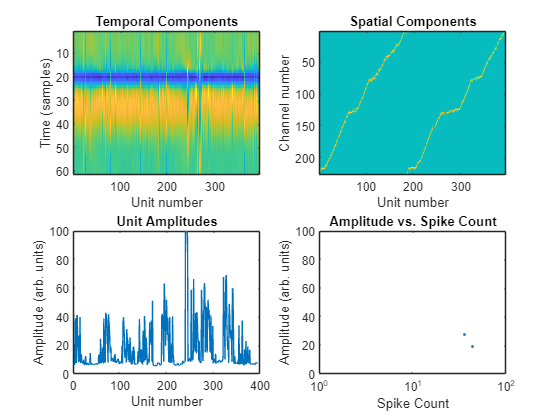

time 0.00, GROUP 1/228, units 0 
time 0.01, GROUP 6/228, units 0 
time 0.02, GROUP 11/228, units 0 
time 0.03, GROUP 16/228, units 0 
time 0.04, GROUP 21/228, units 0 
time 0.05, GROUP 26/228, units 0 
time 0.06, GROUP 31/228, units 0 
time 0.06, GROUP 36/228, units 0 
time 0.07, GROUP 41/228, units 0 
time 0.08, GROUP 46/228, units 0 
time 0.09, GROUP 51/228, units 0 
time 0.10, GROUP 56/228, units 0 
time 0.11, GROUP 61/228, units 0 
time 0.13, GROUP 66/228, units 0 
time 0.14, GROUP 71/228, units 0 
time 0.16, GROUP 76/228, units 0 
time 0.17, GROUP 81/228, units 0 
time 0.18, GROUP 86/228, units 0 
time 0.18, GROUP 91/228, units 0 
time 0.19, GROUP 96/228, units 0 
time 5.69, GROUP 101/228, units 11 
time 10.91, GROUP 106/228, units 16 
time 15.89, GROUP 111/228, units 28 
time 17.53, GROUP 116/228, units 32 
time 32.86, GROUP 121/228, units 60 
time 43.55, GROUP 126/228, units 71 
time 46.06, GROUP 131/228, units 77 
time 47.93, GROUP 136/228, units 82 
time 49.58, GROUP 141/228, 

ans = 49

initialized spike counts
merged 136 into 129 
merged 149 into 148 
merged 119 into 120 
merged 38 into 52 
merged 48 into 36 
merged 40 into 55 
merged 5 into 1 
merged 164 into 162 
merged 147 into 142 


ans = 44

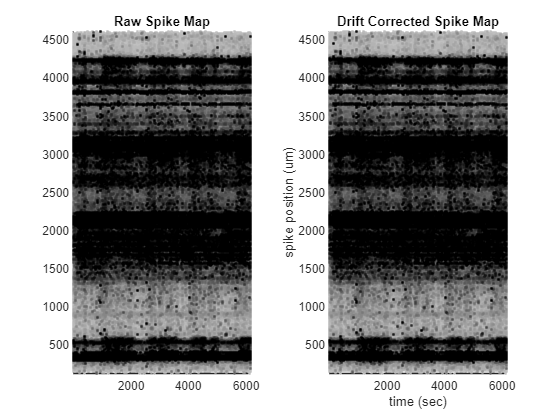

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [227×1 double]
                 yc: [227×1 double]
            xcoords: [227×1 double]
            ycoords: [227×1 double]
               Wrot: [227×227 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×227 gpuArray]
               dist: [10×2038 single]
              iorig: [1414×1 double]
             dshift: [1414×5 double]
                st0: [6751551×6 double]
                  F: [906×20×1414 double]
                 F0: [906×20 gpuArray]
                F0m: [906×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×2038 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14662','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
chanmap_file = dir(fullfile(path_to_rec_dir,'Processed','*.kilosort','channelmap_probe*'));
for probeNum = 1:length(chanmap_file)
    chanmap = load(fullfile(chanmap_file(probeNum).folder,chanmap_file(probeNum).name));
    numChannels = length(chanmap.chanMap);
    runKilosort3(fullfile(path_to_rec_dir,'Processed'),'probeNum',probeNum,'numChannels',numChannels)
end


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


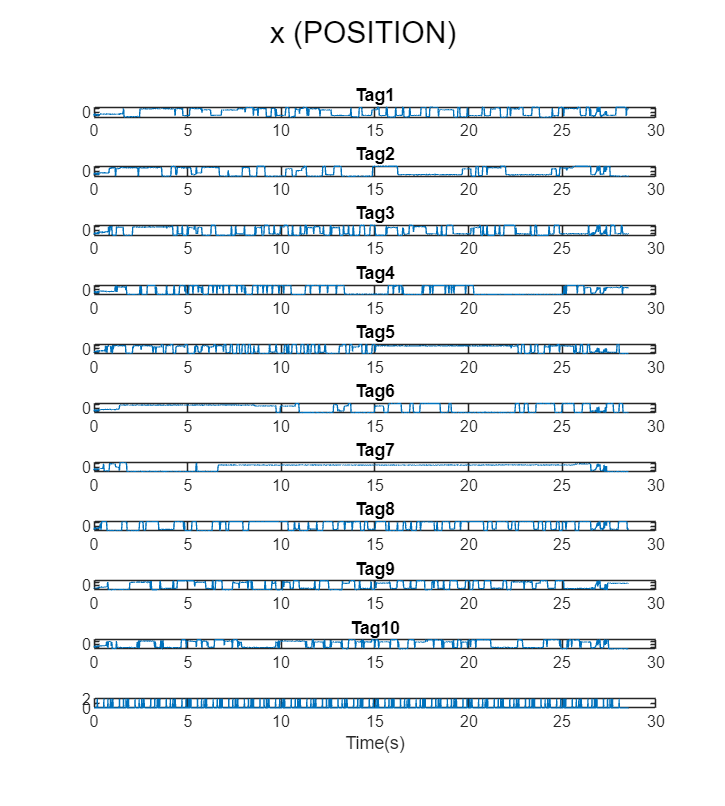

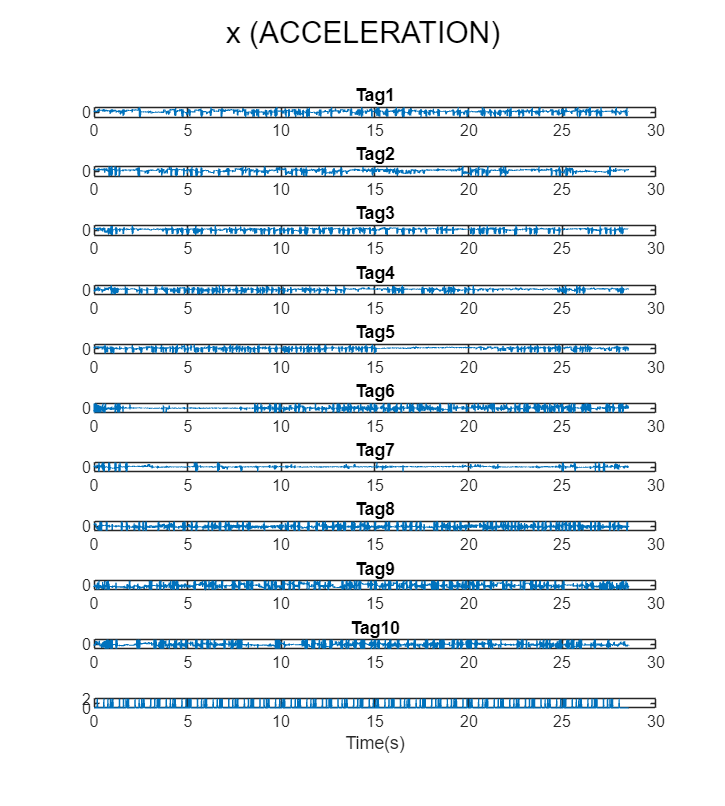

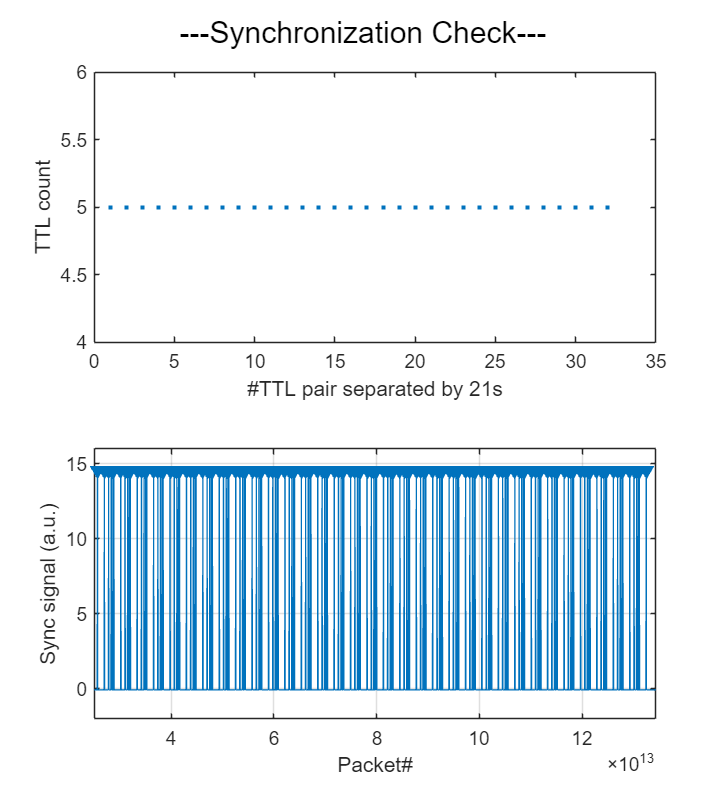

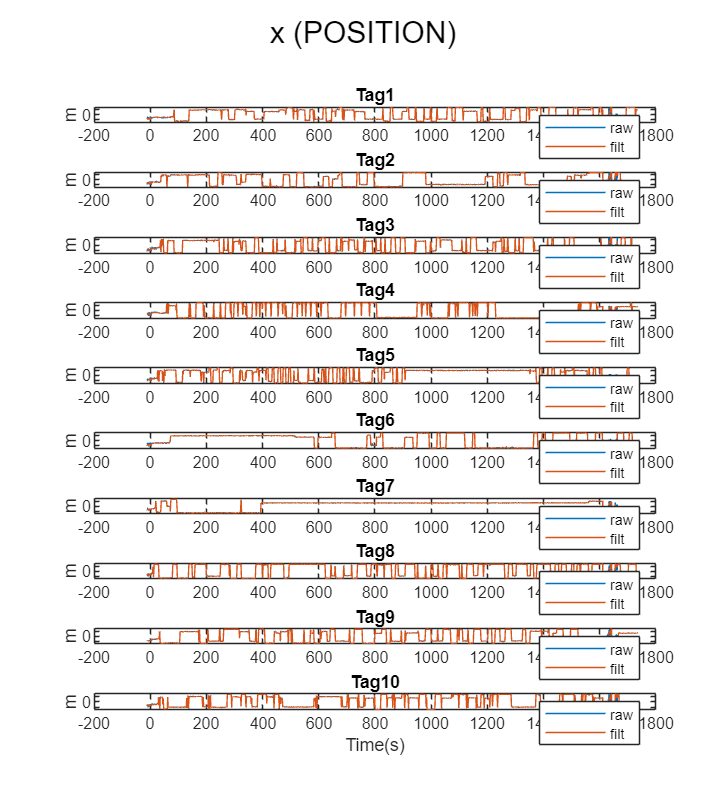

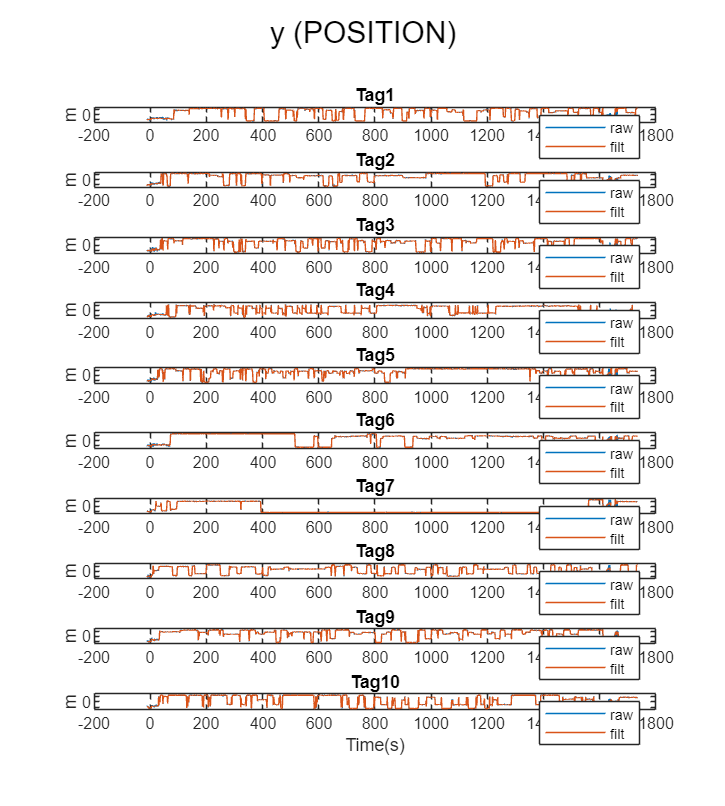

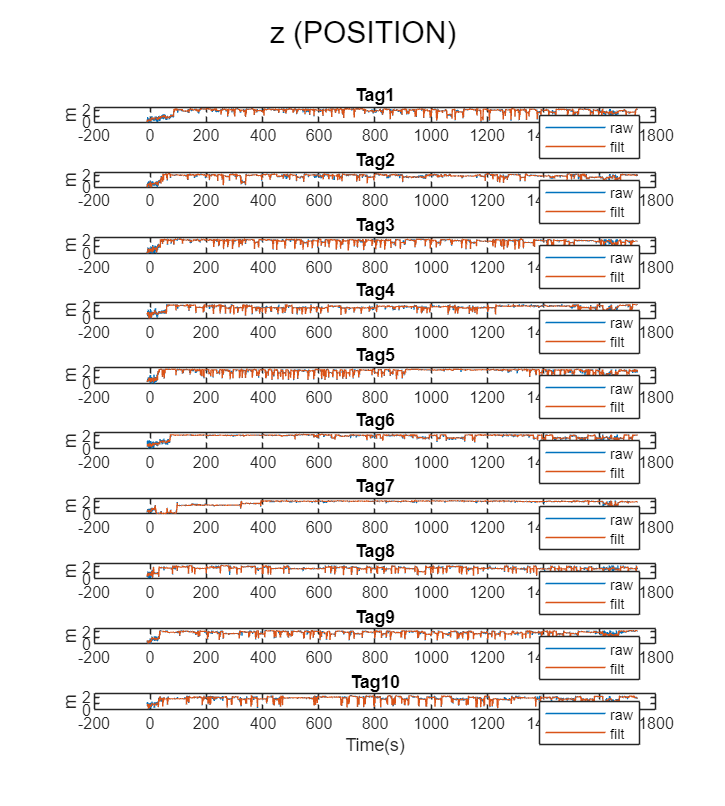

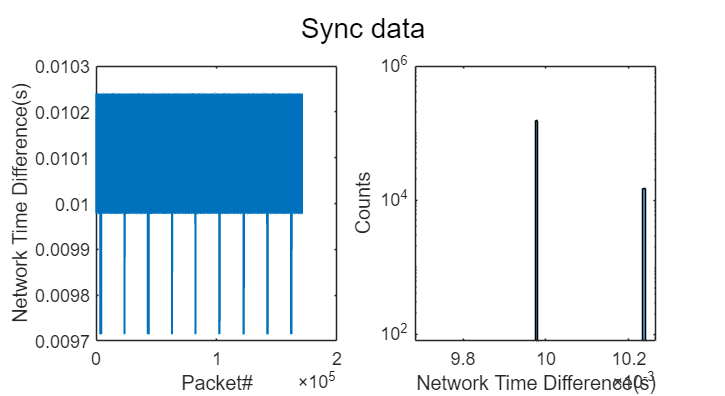

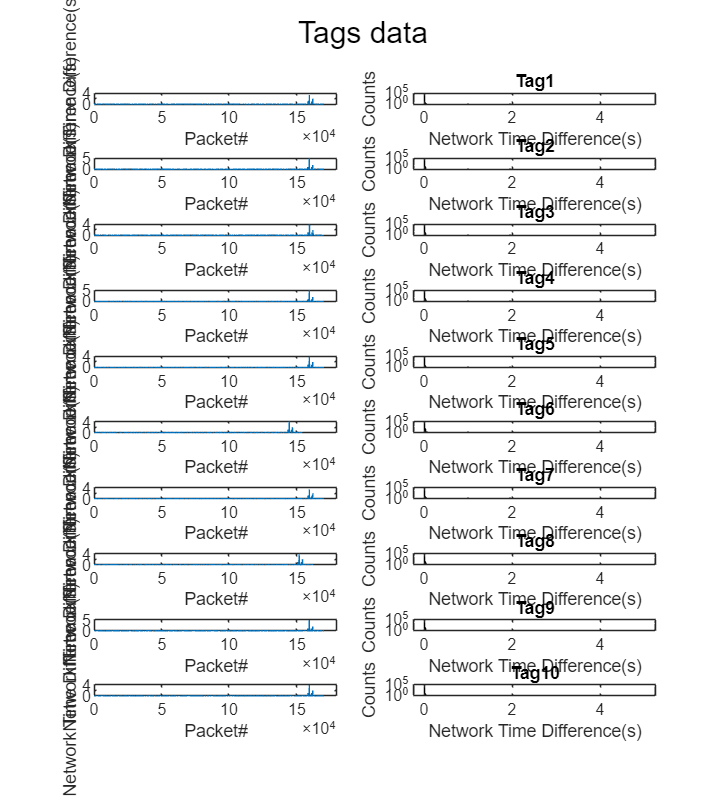

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


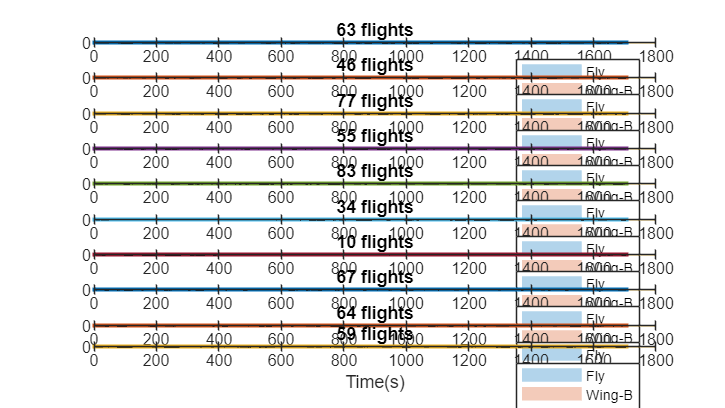

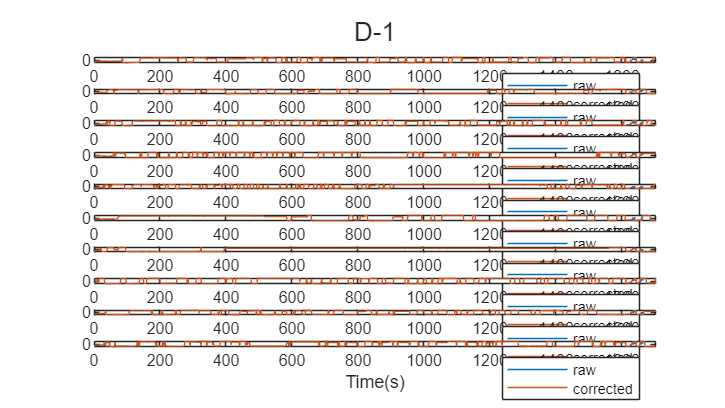

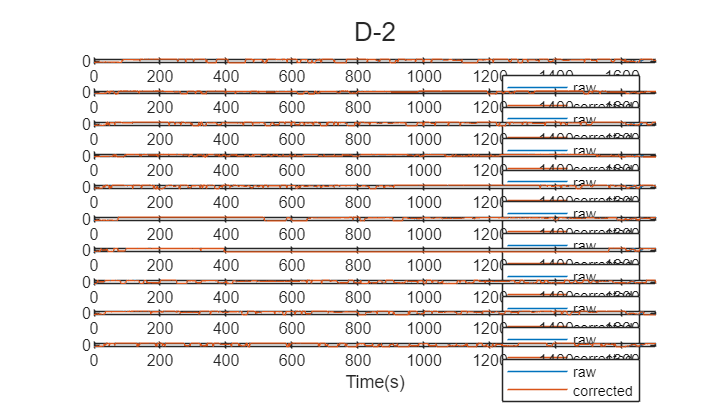

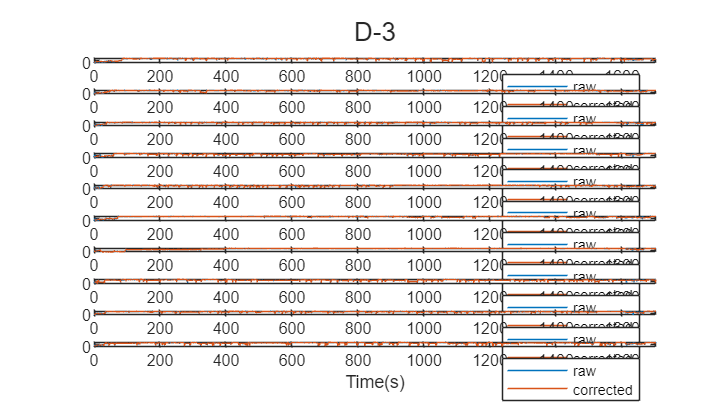

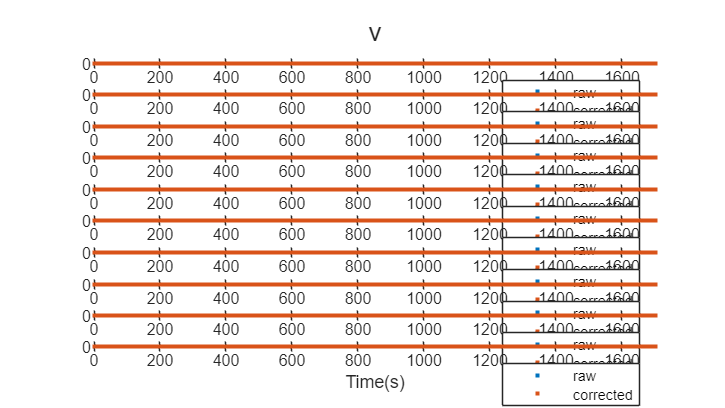

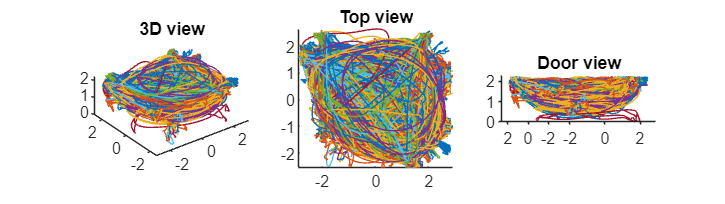

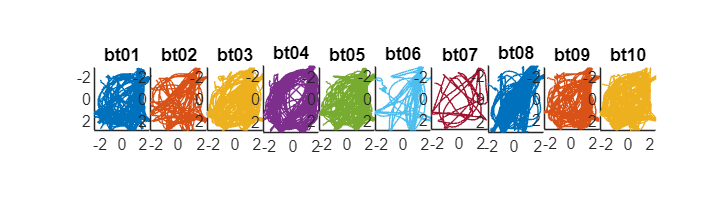

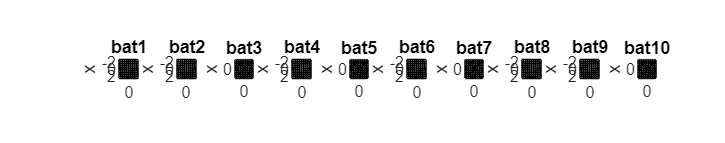

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);